# Enviroment representation

Names: **Iván López Buira & José García Torres  -  G11[F]**

The following pseudo code will help you to recreate the enviroment as Rosa Robot does.

Moreover will help you in understant all the transformation algebra needed to manage the information.

Keep in mind: 

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

## Given enviroment

Given the table with the patient in an arbitrary pose. Use your previous deliverables.

In fact only fiducials are needed

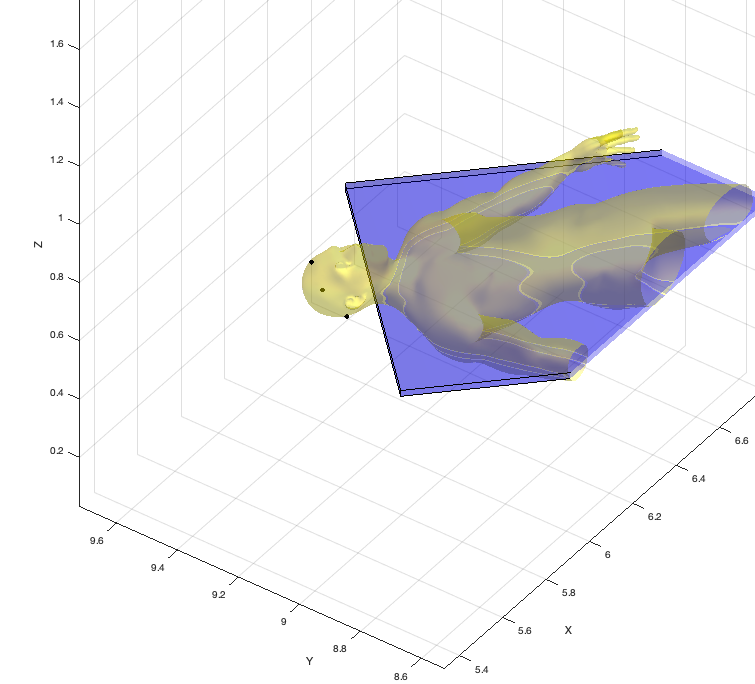

clear
close all
clf

T_M_U = transl(10,8,0.8)*trotz(pi/6); % Reference Frame Taula
T_I_U = troty(pi);

%Fiducial 1
F_1 = eye(4);

F_1(1,4) = 0.0194;
F_1(2,4) = 0.1744;
F_1(3,4) = 0.0448;

%Fiducial 2
F_2 = eye(4);

F_2(1,4) = 0.1330;
F_2(2,4) = 0.1731;
F_2(3,4) = 0.0910;

%Fiducial 3
F_3 = eye(4);

F_3(1,4) = 0.0721;
F_3(2,4) = 0.0372;
F_3(3,4) = 0.1316;

%Fiducial 4
T = eye(4);

T(1,4) = 0.0824;
T(2,4) = 0.0603;
T(3,4) = 0.1078;

## Robot Frame wrt {U}

The Robot Rosa is located near by the patient 

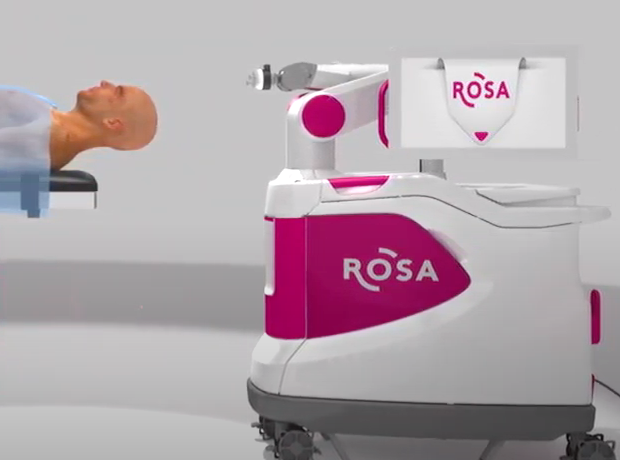

Locating the Robot. Understand the code

robot_loation=transl(5.75,9.75,0)*trotz(-pi/4)

robot_loation =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


mdl_puma560;
p560.base=robot_loation

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.75, 9.75, 0), RPY/xyz = (-45, 0, 0) deg          
 


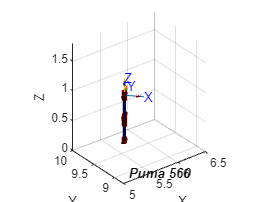

p560.plot(qr,'zoom',1.5)
axis([5 6.5 8.8 10 0 1.8])

T_R_U=p560.base.T

T_R_U =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


## Fiducial wrt {U}

To emulate the action of measuring the fiducial wrt Robot Frame use your fiducials coordinate wrt {U}.

% Declare your fiducial coordinates
F1= F_1(1:3,4)

F1 =     0.0194
    0.1744
    0.0448


F2= F_2(1:3,4)

F2 =     0.1330
    0.1731
    0.0910


F3= F_3(1:3,4)

F3 =     0.0721
    0.0372
    0.1316


## Transform compound needed

We will need the following Reference Frames: {U}, {R}, {F}, {I} 

and the Following Transformation: $ {}_R^U{T,{}_F^R{T,{}_I^F{Tand{}_I^R{T$to correctly face the problem.

It is clear that we will need the transformation Image to Robot, i.e. ${}_I^R{T$ to correctly make the tumor surgery.

Remeber the doctor, based on the Dicom image locate the Tumor (i.e Reference Image {I}) .

## Fiducial in RF Robot {R}

Notice: You have fiducial in RF {U}={A } and you want it in RF{R}={B} ... So  ${}^BP = {}_B^A{T^{ - 1}}{}^AP$

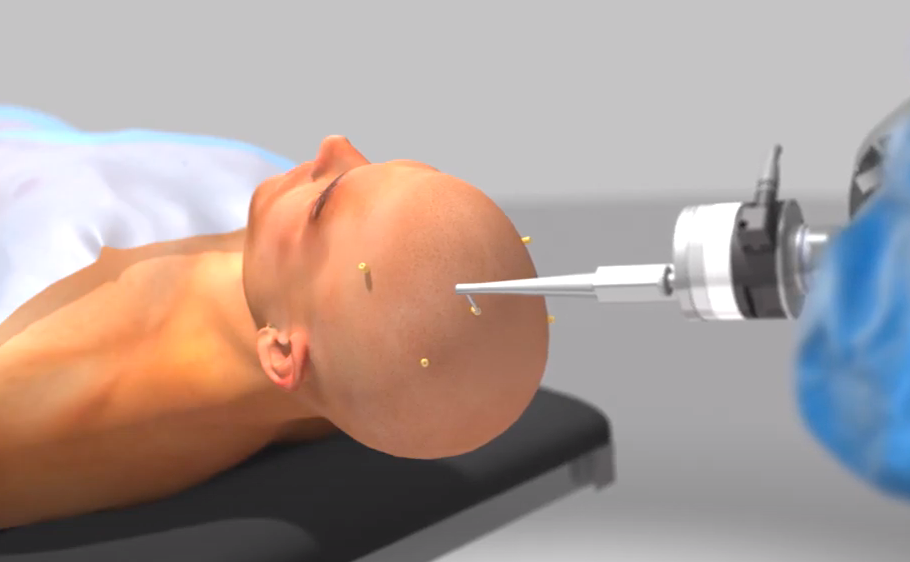

Fi_R=inv(T_R_U)*[F1 F2 F3;ones(1,3)]

Fi_R =     2.7188    2.8001    2.8531
  -10.8231  -10.7437  -10.8829
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


## RF Fiducial {F} wrt RF {R}

It is needed to use an auxiliary Reference Frame formed by the three fiducials because they are measured by the Robot using the teach Tool (See above section) and the Computed Tomography (Dicom images).

We will use the fiducials in RF {R}

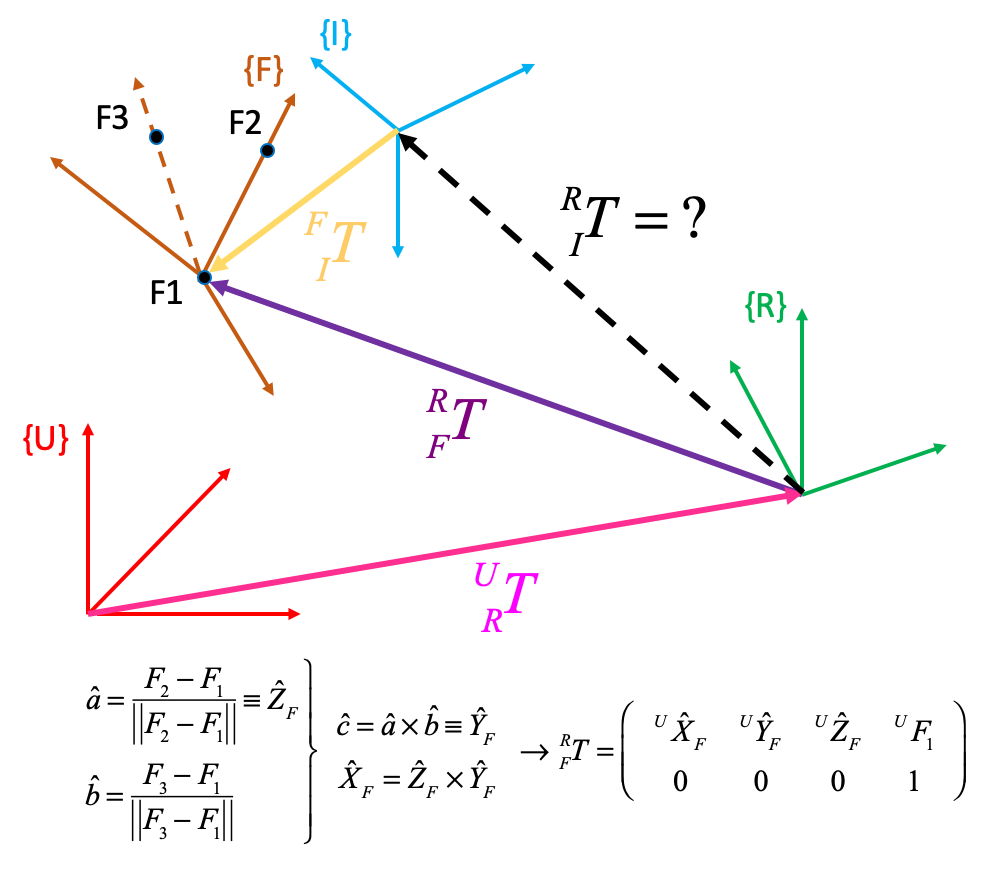

### Orientation wrt {R}

As a matter the example. 

Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b  = (Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));

### Hand made frame description   

${}_F^R{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{R}

T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,3)]]

T_F_R =    -0.5317    0.6625    0.5276    2.8531
    0.7607    0.6475   -0.0464  -10.8829
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


Checking the rotation matrix

The determinan must be 1

det(T_F_R(1:3,1:3))

ans = 1

## RF Fiducial {F} wrt RF {U}

The answer to this question is ${}_F^U{T={}_R^U{T{}_F^R{T$

We needed  ${}_F^U{T$to draw it in RF {U}

T_F_U=T_R_U * T_F_R

T_F_U =     0.1619    0.9263    0.3403    0.0721
    0.9139   -0.0106   -0.4059    0.0372
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


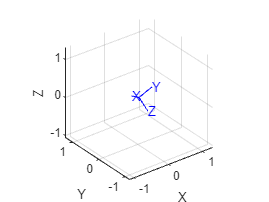

trplot(T_F_U,'Frame','F','color', 'b','length',0.4)

## Fiducials wrt {I} 

Taking data from Dicom images

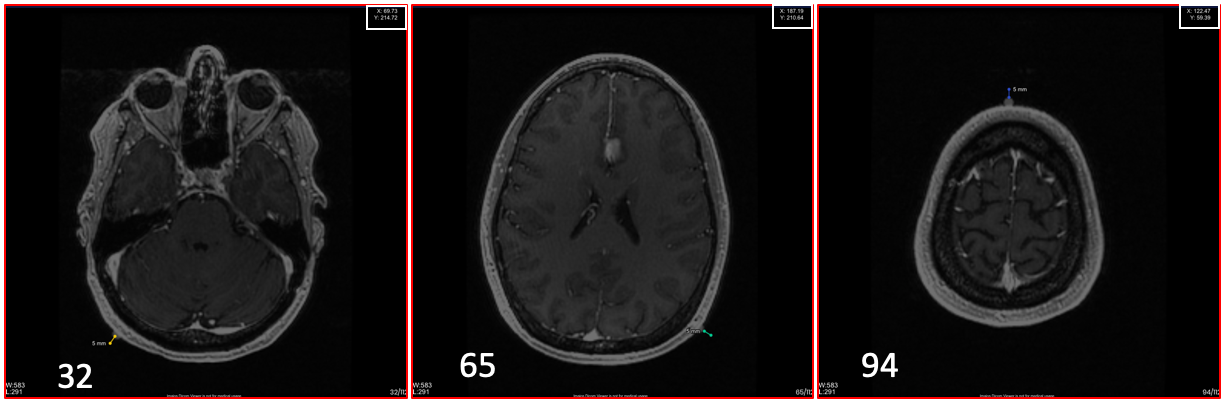

pitch =1.4; % Pitch among slices 
F1D = [F_1(1,4) F_1(2,4) 0.032*pitch]'; %image #32
F2D = [F_2(1,4) F_2(2,4) 0.065*pitch]'; %image #65
F3D = [F_3(1,4) F_3(2,4) 0.094*pitch]'; %image #94
Tumor=[T(1,4) T(2,4) 0.078*pitch]'; %image #78

## Visualizing fiducials and tumor

Use your previous deliverables

### Image Frame 

Plotting Image Reference Frame at origen of Reference Frame Univers {U}

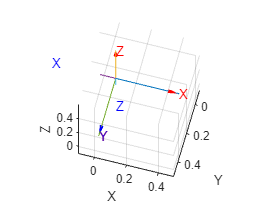

trplot(eye(3),'Frame','U','color', 'r','length',0.4, 'arrow','width',0.4)
hold on
%trplot(T_I_U, 'Frame', 'I', 'color', 'b', 'length', 0.4, 'arrow', 'width', 0.4)

axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65) % For better understanding

### Fiducials and tumor in {I} 

We use a sphere to represent a fiducial

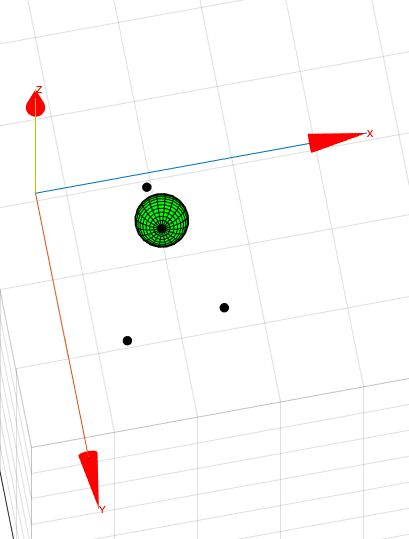

% Fiducials

hold on
[X,Y,Z] = sphere;
r=0.005;

X2 = X * r

X2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0008   -0.0007   -0.0006   -0.0005   -0.0002    0.0000    0.0002    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0005    0.0002    0.0000   -0.0002   -0.0005   -0.0006   -0.0007   -0.0008
   -0.0015   -0.0015   -0.0013   -0.0009   -0.0005    0.0000    0.0005    0.0009    0.0013    0.0015    0.0015    0.0015    0.0013    0.0009    0.0005    0.0000   -0.0005   -0.0009   -0.0013   -0.0015   -0.0015
   -0.0023   -0.0022   -0.0018   -0.0013   -0.0007    0.0000    0.0007    0.0013    0.0018    0.0022    0.0023    0.0022    0.0018    0.0013    0.0007    0.0000   -0.0007   -0.0013   -0.0018   -0.0022   -0.0023
   -0.0029   -0.0028   -0.0024   -0.0017   -0.0009    0.0000    0.0009    0.0017    0.0024    0.0028    0.0029    0.0028    0.0024    0.0017    0.0009 

Y2 = Y * r

Y2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0002   -0.0005   -0.0006   -0.0007   -0.0008   -0.0007   -0.0006   -0.0005   -0.0002         0    0.0002    0.0005    0.0006    0.0007    0.0008    0.0007    0.0006    0.0005    0.0002         0
         0   -0.0005   -0.0009   -0.0013   -0.0015   -0.0015   -0.0015   -0.0013   -0.0009   -0.0005         0    0.0005    0.0009    0.0013    0.0015    0.0015    0.0015    0.0013    0.0009    0.0005         0
         0   -0.0007   -0.0013   -0.0018   -0.0022   -0.0023   -0.0022   -0.0018   -0.0013   -0.0007         0    0.0007    0.0013    0.0018    0.0022    0.0023    0.0022    0.0018    0.0013    0.0007         0
         0   -0.0009   -0.0017   -0.0024   -0.0028   -0.0029   -0.0028   -0.0024   -0.0017   -0.0009         0    0.0009    0.0017    0.0024    0.0028 

Z2 = Z * r

Z2 =    -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050
   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049   -0.0049
   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048
   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045
   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040 


surf(F_1(1,4)+X2,F_1(2,4)+Y2,F_1(3,4)+Z2,'FaceColor',[1 0 0])
surf(F_2(1,4)+X2,F_2(2,4)+Y2,F_2(3,4)+Z2,'FaceColor',[1 0 0])
surf(F_3(1,4)+X2,F_3(2,4)+Y2,F_3(3,4)+Z2,'FaceColor',[1 0 0])

hold on

% Tumor

r = 0.0173;

X2 = X * r

X2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0027   -0.0026   -0.0022   -0.0016   -0.0008    0.0000    0.0008    0.0016    0.0022    0.0026    0.0027    0.0026    0.0022    0.0016    0.0008    0.0000   -0.0008   -0.0016   -0.0022   -0.0026   -0.0027
   -0.0053   -0.0051   -0.0043   -0.0031   -0.0017    0.0000    0.0017    0.0031    0.0043    0.0051    0.0053    0.0051    0.0043    0.0031    0.0017    0.0000   -0.0017   -0.0031   -0.0043   -0.0051   -0.0053
   -0.0079   -0.0075   -0.0064   -0.0046   -0.0024    0.0000    0.0024    0.0046    0.0064    0.0075    0.0079    0.0075    0.0064    0.0046    0.0024    0.0000   -0.0024   -0.0046   -0.0064   -0.0075   -0.0079
   -0.0102   -0.0097   -0.0082   -0.0060   -0.0031    0.0000    0.0031    0.0060    0.0082    0.0097    0.0102    0.0097    0.0082    0.0060    0.0031 

Y2 = Y * r

Y2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0008   -0.0016   -0.0022   -0.0026   -0.0027   -0.0026   -0.0022   -0.0016   -0.0008         0    0.0008    0.0016    0.0022    0.0026    0.0027    0.0026    0.0022    0.0016    0.0008         0
         0   -0.0017   -0.0031   -0.0043   -0.0051   -0.0053   -0.0051   -0.0043   -0.0031   -0.0017         0    0.0017    0.0031    0.0043    0.0051    0.0053    0.0051    0.0043    0.0031    0.0017         0
         0   -0.0024   -0.0046   -0.0064   -0.0075   -0.0079   -0.0075   -0.0064   -0.0046   -0.0024         0    0.0024    0.0046    0.0064    0.0075    0.0079    0.0075    0.0064    0.0046    0.0024         0
         0   -0.0031   -0.0060   -0.0082   -0.0097   -0.0102   -0.0097   -0.0082   -0.0060   -0.0031         0    0.0031    0.0060    0.0082    0.0097 

Z2 = Z * r

Z2 =    -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173   -0.0173
   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171
   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165   -0.0165
   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154
   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140 

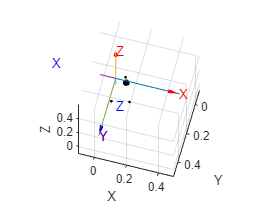


surf(T(1,4)+X2,T(2,4)+Y2,T(3,4)+Z2,'FaceColor',[1 0 0])


triangle = [F_1(1:3,4), F_2(1:3,4), F_3(1:3,4)];


## T_F_I - Frame Description 

As we mention before It is needed to use the Fiducial as auxiliary Reference Frame 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before with the fiducial in RF {U}

### Orientation 

YfD = (F2D - F1D) / norm(F2D - F1D);
bD = (F3D - F1D) / norm(F3D - F1D);
ZfD = cross(YfD, bD) / norm(cross(YfD, bD));
XfD = cross(YfD, ZfD) / norm(cross(YfD, ZfD));

AB = (triangle(1:3,2) - triangle(1:3,1)) / norm(triangle(1:3,1) - triangle(1:3,2)); % Vector pointing A 
CB = (triangle(1:3,3) - triangle(1:3,1)) / norm(triangle(1:3,1) - triangle(1:3,3)); % Vector pointing C
Z_B = cross(CB, AB) / norm(cross(CB, AB));
orientAB = oa2r(AB, Z_B);

% AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); 
% CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); 
% Z_B = cross(CB, AB) / norm(cross(CB, AB));                                          
% O_B_A = oa2r(AB, Z_B);                

% AB = (triangle(1:3,1) - triangle(1:3,3)) / norm(triangle(1:3,3) - triangle(1:3,1)); 
% CB = (triangle(1:3,2) - triangle(1:3,3)) / norm(triangle(1:3,2) - triangle(1:3,3)); 
% Z_B = cross(CB, AB) / norm(cross(CB, AB));                                          
% O_B_A = oa2r(AB, Z_B);           



### Frame Description  

${}_F^I{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{I}

T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F3D;1]]

T_F_I =     0.1619    0.9263    0.3403    0.0721
    0.9139   -0.0106   -0.4059    0.0372
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


T_F_I_a = [orientAB F_1(1:3,4); 0 0 0 1];
%T_F_I = [O_B_A I2(1:3,4); 0 0 0 1];
%T_F_I = [O_B_A I3(1:3,4); 0 0 0 1];
det(T_F_I)

ans = 1.0000

### Visualizing T_F_I

Fiducial Reference Frame wrt Reference frame {I} at origen of {U}

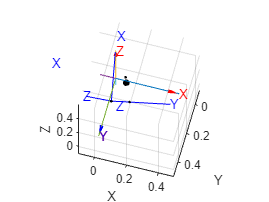

%scatter3(F1D(1,1),F1D(2,1),F1D(3,1), 'o')
trplot(T_F_I_a,'Frame','F','color', 'b','length',0.4)

## RF Image {I} wrt RF {U}

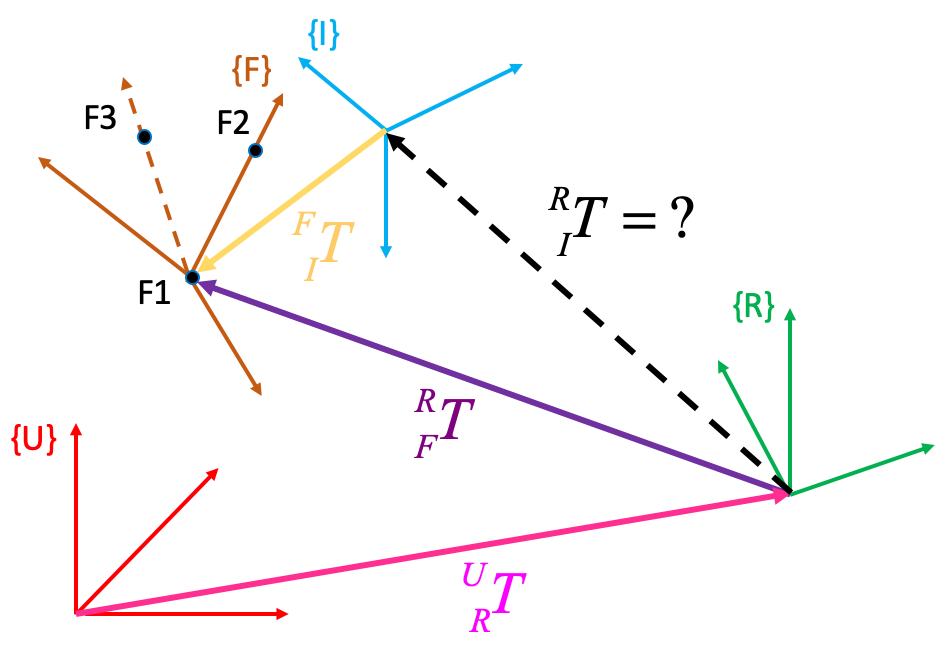

We have the Reference Frame {F} wrt {U} ${}_F^U{T={}_R^U{T{}_F^R{T$ and also ${}_F^I{T $, so ... ${}_I^U{T={}_F^U{T{}_F^I{T^{-1}$

T_I_U=T_F_U*inv(T_F_I)

T_I_U =     1.0000   -0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000   -0.0000
   -0.0000   -0.0000    1.0000    0.0000
         0         0         0    1.0000


Ckeck that ${}_I^U{T$ is coincident with the given Image Reference Frame 

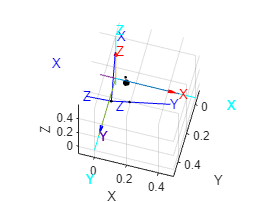

%trplot(T_I_U,'Frame','I','color', 'cyan','length',0.7)

## T_I_R System equation


$$ {}_I^U{T={}_F^U{T{}_F^I{T^{-1}={}_R^U{T{}_I^R{T\\
{}_I^R{T={}_R^U{T^{-1}{}_F^U{T{}_F^I{T^{-1}$$


T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)

T_I_R =     0.7071   -0.7071    0.0000    2.8284
    0.7071    0.7071    0.0000  -10.9602
   -0.0000   -0.0000    1.0000    0.0000
         0         0         0    1.0000


## Overall ckecking

### Fiducials in Robot Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Robot Reference Frame

Fi_R2=T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     2.7188    2.8001    2.8531
  -10.8231  -10.7437  -10.8829
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


Fi_R

Fi_R =     2.7188    2.8001    2.8531
  -10.8231  -10.7437  -10.8829
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


### Fiducials in Univers Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Univers Reference Frame.

Fi_R2=T_R_U*T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     0.0194    0.1330    0.0721
    0.1744    0.1731    0.0372
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


## Summary

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

e) You can draw tumor, containing box, human and table and you can represent all the RF's

## How I will ckeck 

Next Laboratory session I will give you the Rosa Robot information: i.e the Fiducials coordinates in RF {R}

and you will have to recreate all the enviroment. (containing box, human, table and all RF's)

There will be no second round, that is, I will mark your result.